# Setup

% Add paths for SDETools
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\SDETools'
addpath './functions'

% Default Parameters
dt = 0.02; 
tmax = 10000;
t = 0:dt:tmax;   
N = 100;
h = 0.1;                     
theta = 6;
sig = 1;

Original model

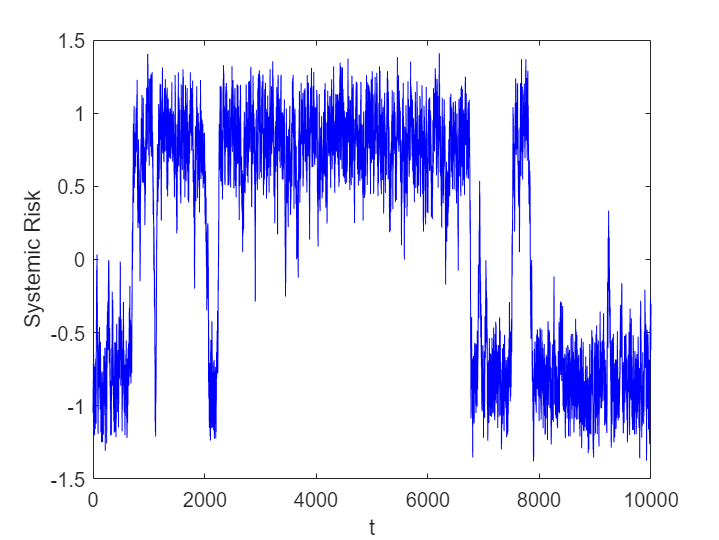

x = SolveSDE(t, N, h, sig, theta, @(t, x) (mean(x) - x));
PlotSDE(t, x);

## Impact of different network structures on default state

There are $N$ banks. Define $\mathbf{A}_{t}$ to be an $N \times N$ directed unweighted adjacency matrix of the network structure at time $t$. $A_{ijt$ is the element in row $i$ and column$j$ of $\mathbf{A}_{t}$, which indicates whether bank $i$ receives funds from bank$j$ at time $t$.

 Heterophily

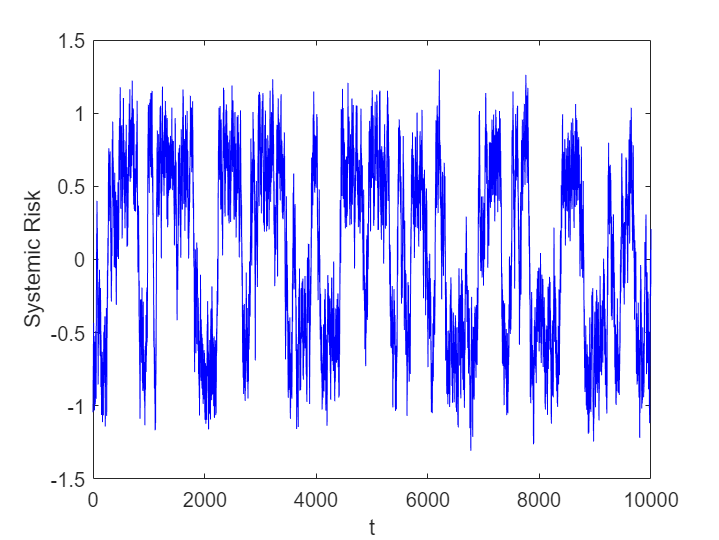

threshold = 1;
x = SolveSDE(t, N, h, sig, theta, @(t, x) heterophily(x, threshold));
PlotSDE(t, x);

Homophily

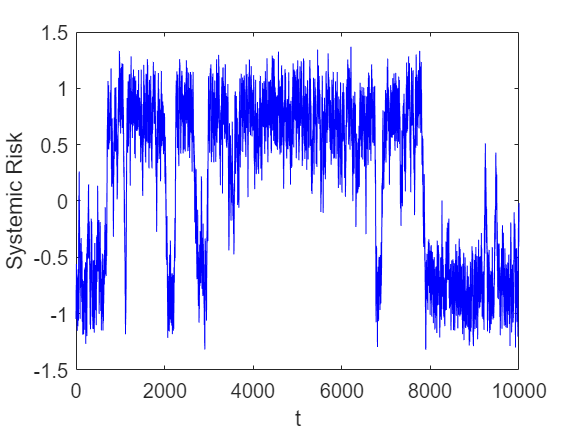

x = SolveSDE(t, N, h, sig, theta, @(t, x) homophily(x, threshold));
PlotSDE(t, x);

Disconnected/Bipartite

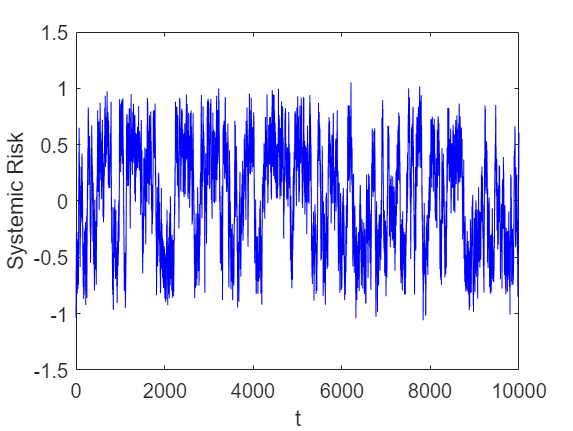

x = SolveSDE(t, N, h, sig, theta, @(t, x) bipartite(x));

PlotSDE(t, x);

Connected

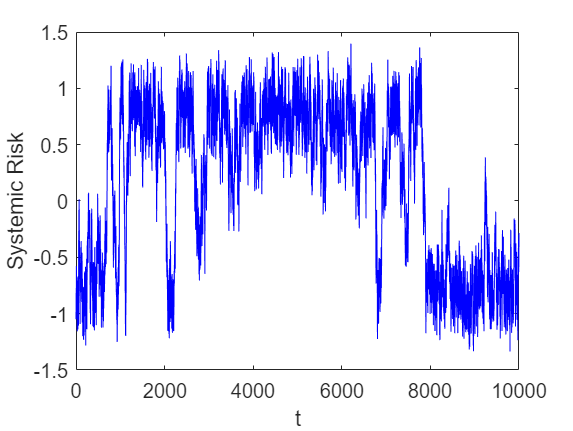

x = SolveSDE(t, N, h, sig, theta, @(t, x) connected(x));
PlotSDE(t, x);

Erdos-Renyi

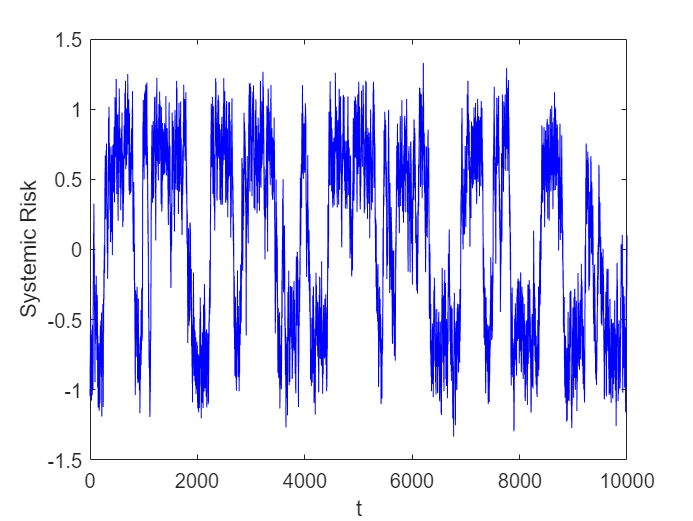

x = SolveSDE(t, N, h, sig, theta, @(t, x) ErdosRenyi(x, 0.5));
PlotSDE(t, x);

Random graph (with p = 0.1)

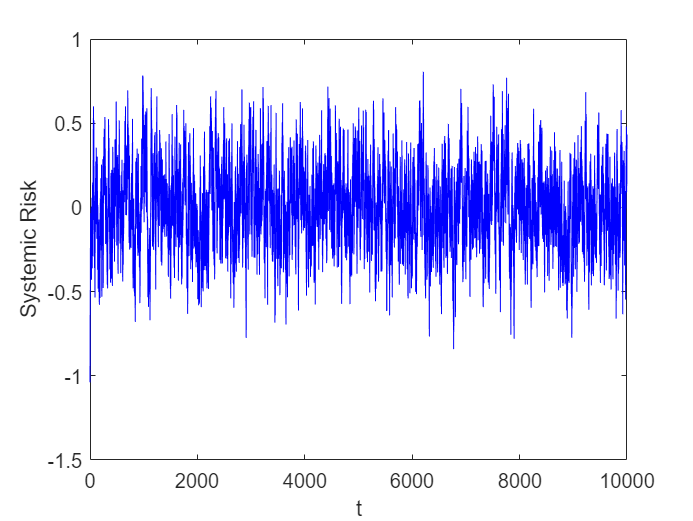

x = SolveSDE(t, N, h, sig, theta, @(t, x) ErdosRenyi(x, 0.1));
PlotSDE(t, x);

Random graph (with p = 0.3)

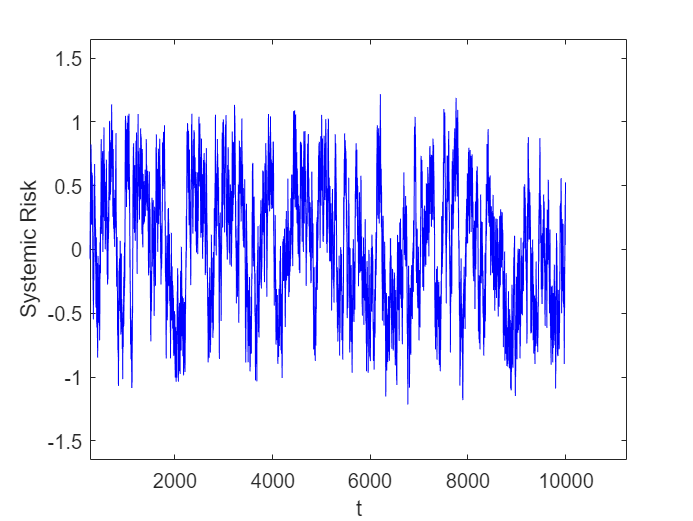

x = SolveSDE(t, N, h, sig, theta, @(t, x) ErdosRenyi(x, 0.3));
PlotSDE(t, x);

Remove Weak Link - weak links only interact with themselves

Threshold value $\tau = 0.5$

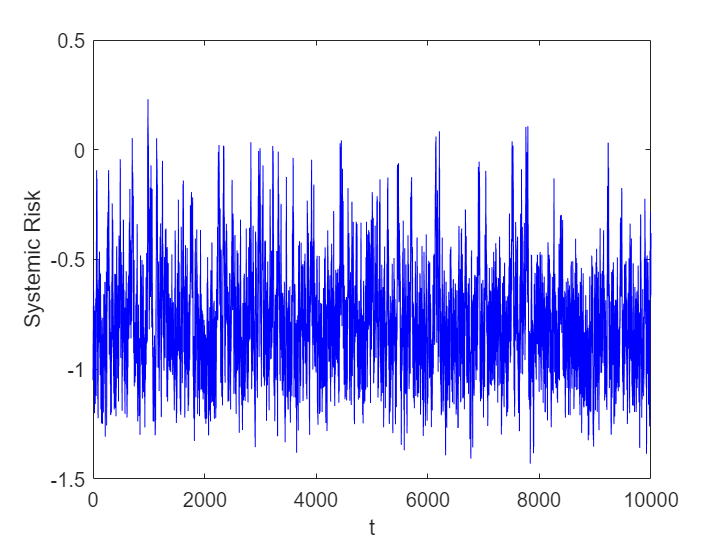

x = SolveSDE(t, N, h, sig, theta, @(t, x) RemoveWeakLink(x, 0.5));
PlotSDE(t, x);

Threshold value $\tau = 1$

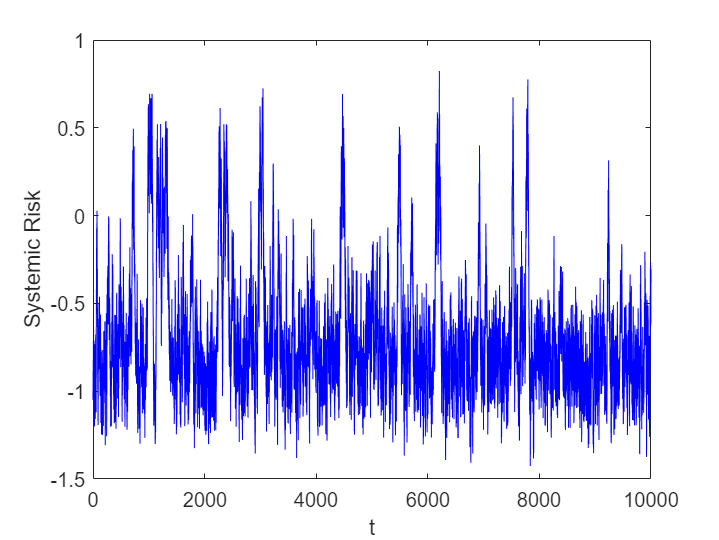

x = SolveSDE(t, N, h, sig, theta, @(t, x) RemoveWeakLink(x, 1));
PlotSDE(t, x);

Remove Weak Link 2 - weak links can only lend, not borrow

Threshold value $\tau = 0$

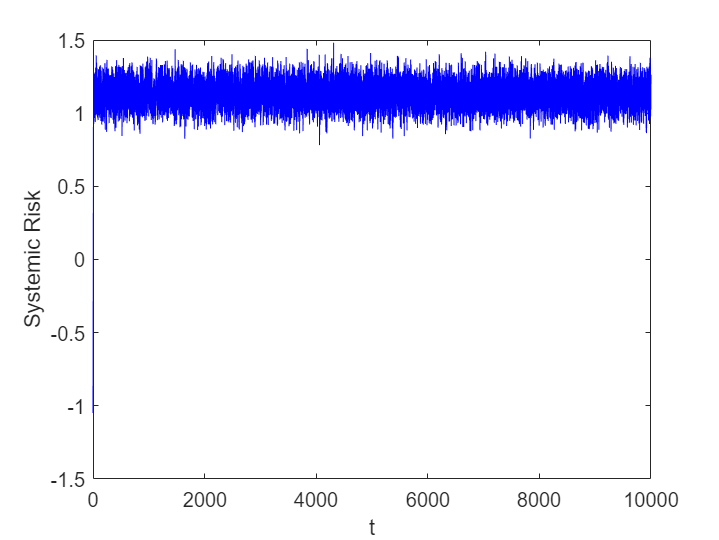

x = SolveSDE(t, N, h, sig, theta, @(t, x) RemoveWeakLink2(x, 0));
PlotSDE(t, x);

Threshold value $\tau = 1$

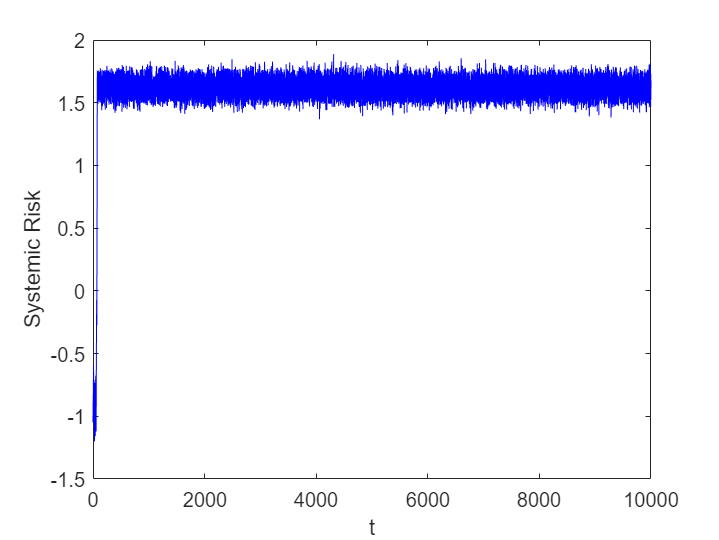

x = SolveSDE(t, N, h, sig, theta, @(t, x) RemoveWeakLink2(x, 1));
PlotSDE(t, x);

Remove Weak Link 3 - weak links can only borrow, not lend

Threshold value $\tau = 0$

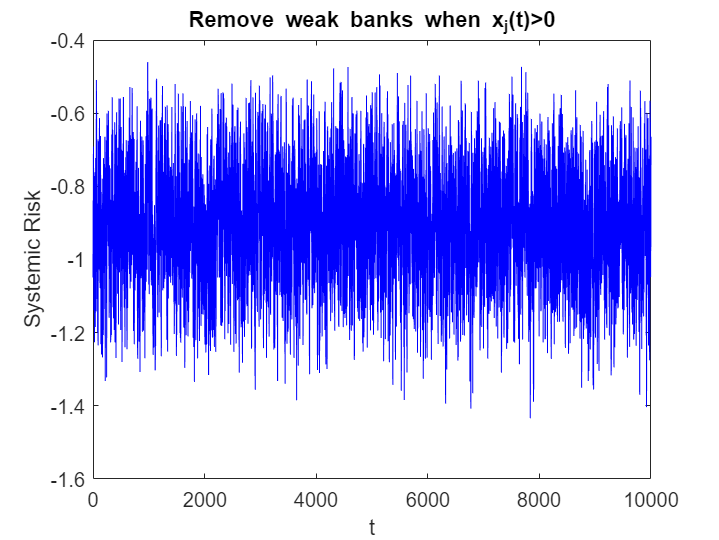

x = SolveSDE(t, N, 0.1, sig, theta, @(t, x) RemoveWeakLink3(x, 0));
PlotSDE(t, x);
title("Remove weak banks when x_{j}(t)>0")

Threshold value $\tau = 0.5$

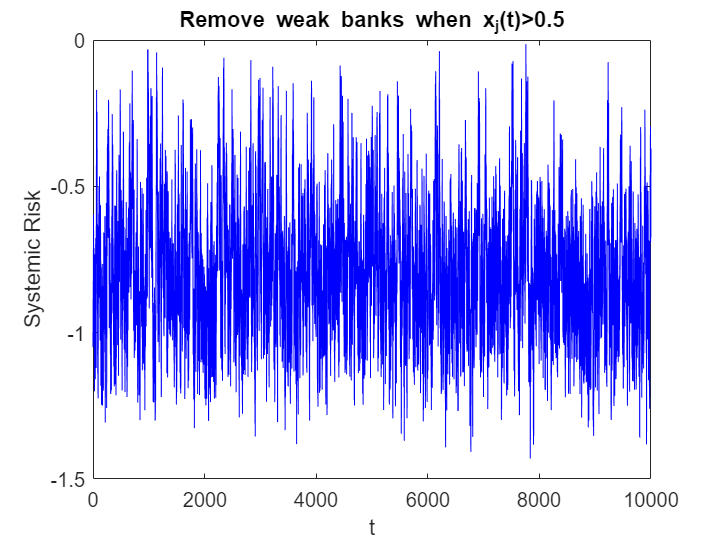

x = SolveSDE(t, N, 0.1, sig, theta, @(t, x) RemoveWeakLink3(x, 0.5));
PlotSDE(t, x);
title("Remove weak banks when x_{j}(t)>0.5")

Threshold value $\tau = 1$

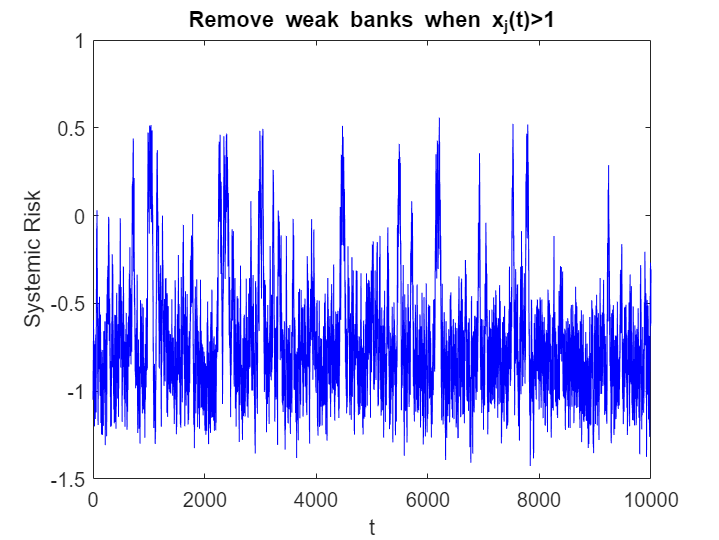

x = SolveSDE(t, N, 0.1, sig, theta, @(t, x) RemoveWeakLink3(x, 1));
PlotSDE(t, x);
title("Remove weak banks when x_{j}(t)>1")

Lower triangular adjacency matrix - BASELINE MODEL

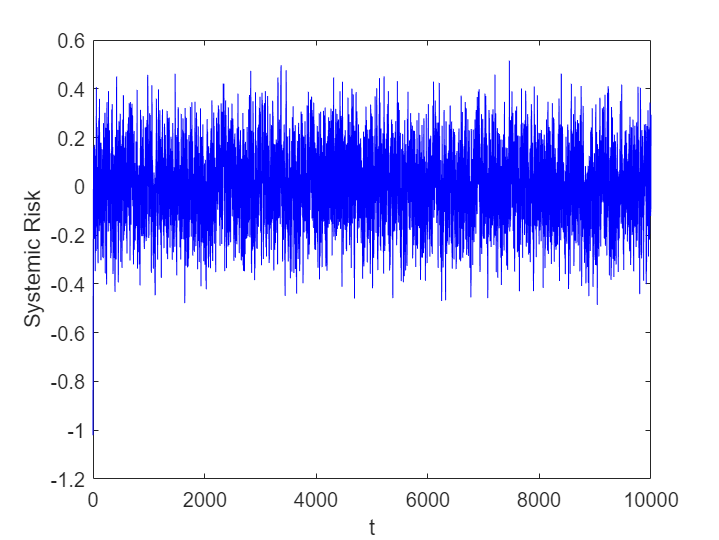

x = SolveSDE(t, N, 1, 1, 1, @(t, x) LowerTriangular(x));
PlotSDE(t, x);

Markov Switching process

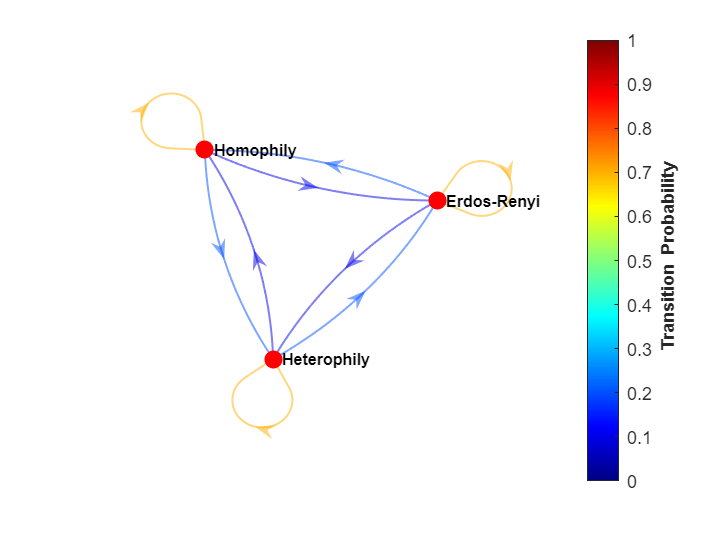

% Define a Markov structure with three fields:

% Field 1: Function Handles (redundant but left in for now)
value1 = {{@(x)homophily(x, 1), @(x)heterophily(x, 1), @(x)ErdosRenyi(x, 0.3)}};
% Field 2: Transition Matrix
P = [0.7, 0.2, 0.1;
     0.1, 0.7, 0.2;
     0.2, 0.1, 0.7];
% Field 3: Initial state
initial_state = 1;

MarkovStruct = struct(...
    'states', value1, ...
    'P', P, ...
    'state', initial_state ...
    );

% Return Markov simulations and markov process
[X, mc] = MarkovSwitching(MarkovStruct, t);

% Plot Markov chain and simulations
graphplot(mc, 'ColorEdges', true);

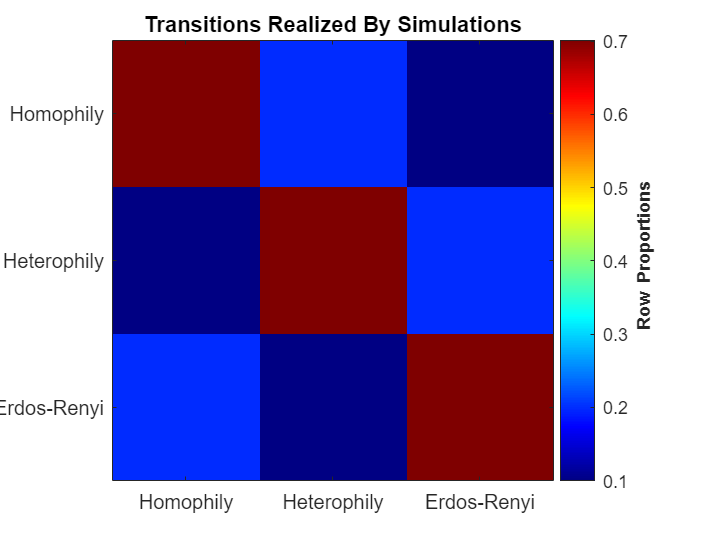

simplot(mc, X, 'Type', 'transitions');

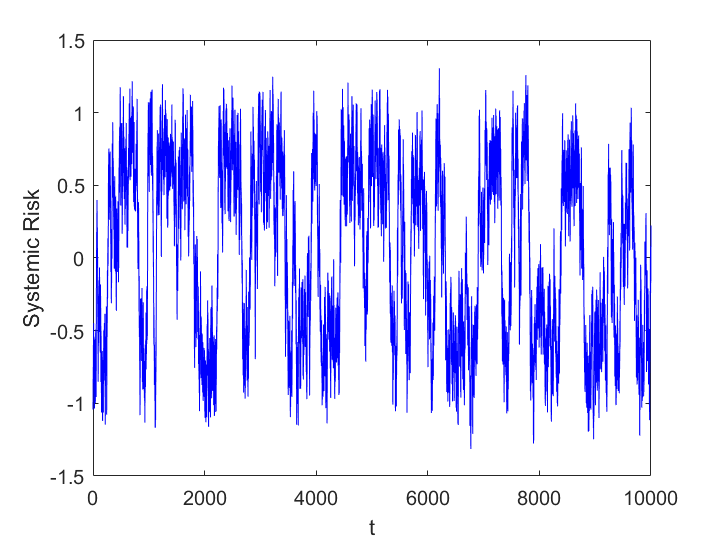


% Solve SDE and plot
x = SolveSDE(t, N, h, sig, theta, @(t, x) EvalMarkov(t, x, X));
PlotSDE(t, x);

Big and Small Banks set-up

rho_l = 0.5; rho_h = 0.5;
rho = [rho_l; rho_h];
theta_l = 5; theta_h = 15;
Theta = [theta_l; theta_h];
theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

Solve SDE:

Original model:

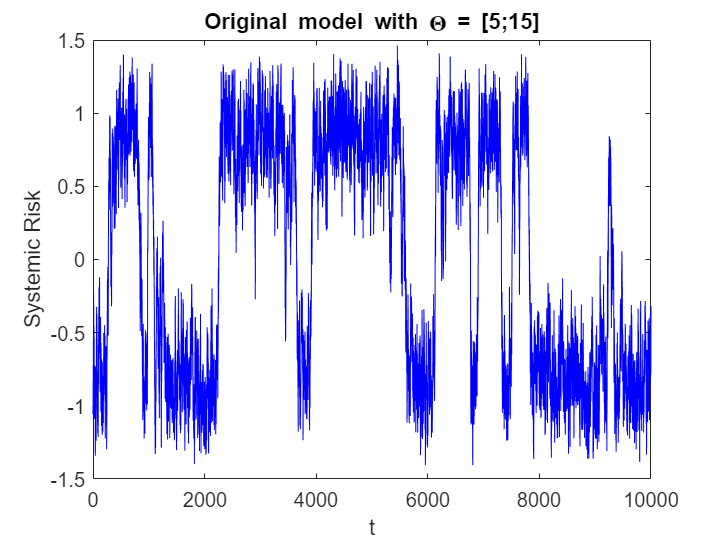

x = SolveSDE(t, N, h, sig, theta, @(t, x) (mean(x) - x));
PlotSDE(t, x);
title("Original model with \Theta = [5;15]")

Removing weak banks before they default

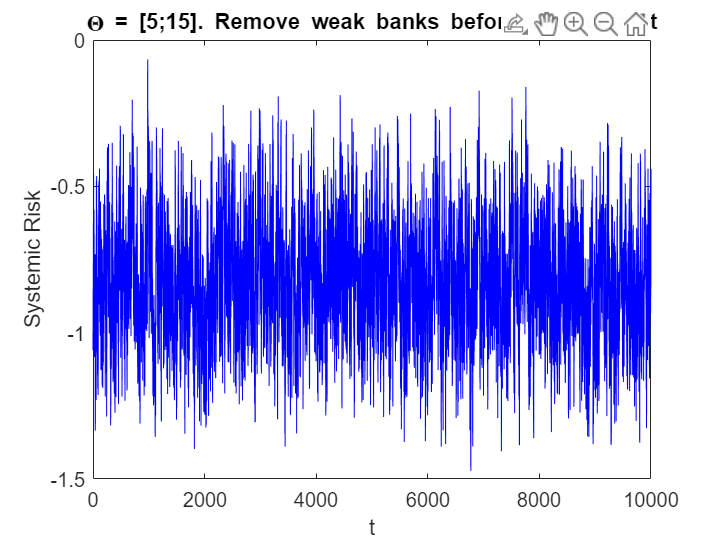

x = SolveSDE(t, N, h, sig, theta, @(t, x) RemoveWeakLink(x, 0));
PlotSDE(t, x);
title("\Theta = [5;15]. Remove weak banks before they default")

Removing weak banks after they default

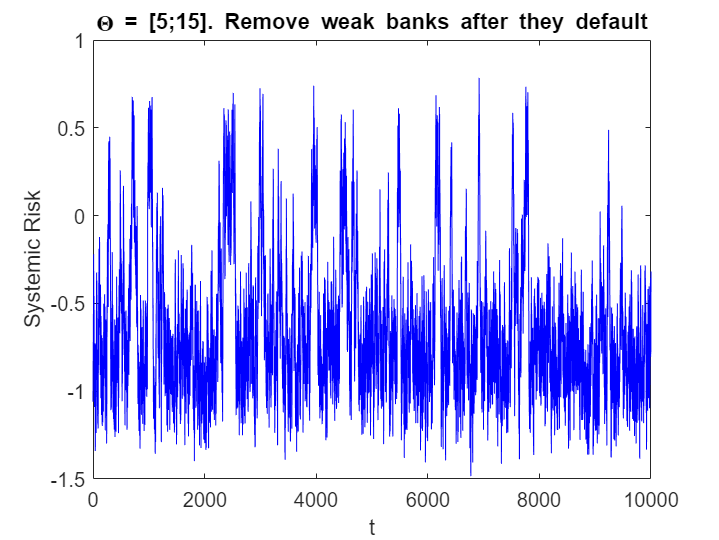

x = SolveSDE(t, N, h, sig, theta, @(t, x) RemoveWeakLink(x, 1));
PlotSDE(t, x);
title("\Theta = [5;15]. Remove weak banks after they default")

Remove weak and big banks

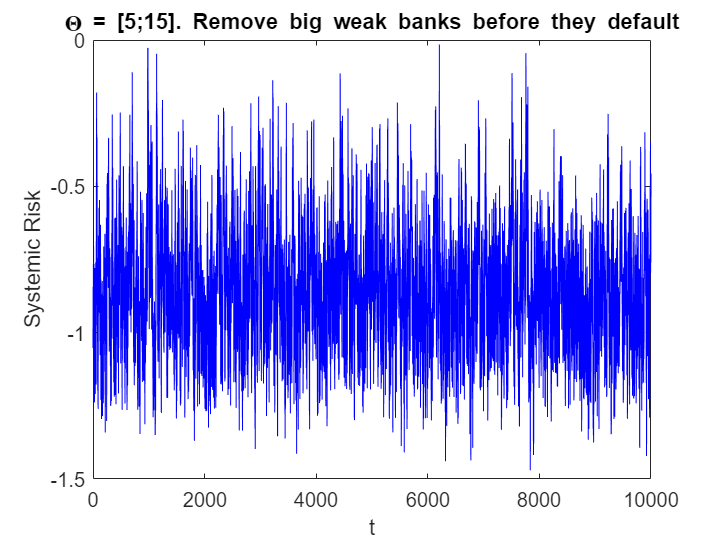

theta = 6;
A = BigSmallGraph(N, 5/6, 2.5, 0.5);
x = SolveSDE(t, N, h, sig, theta, @(t, x) WeakLinkHetero(x, A, 0, 1));
PlotSDE(t, x);
title("\Theta = [5;15]. Remove big weak banks before they default")

Remove weak and big banks

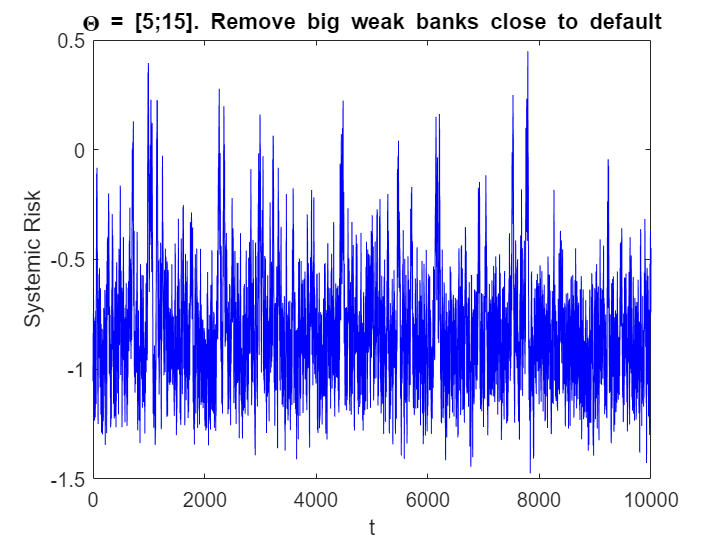

theta = 6;
A = BigSmallGraph(N, 5/6, 2.5, 0.5);
x = SolveSDE(t, N, h, sig, theta, @(t, x) WeakLinkHetero(x, A, 0.5, 1));
PlotSDE(t, x);
title("\Theta = [5;15]. Remove big weak banks close to default")

Remove weak and small banks

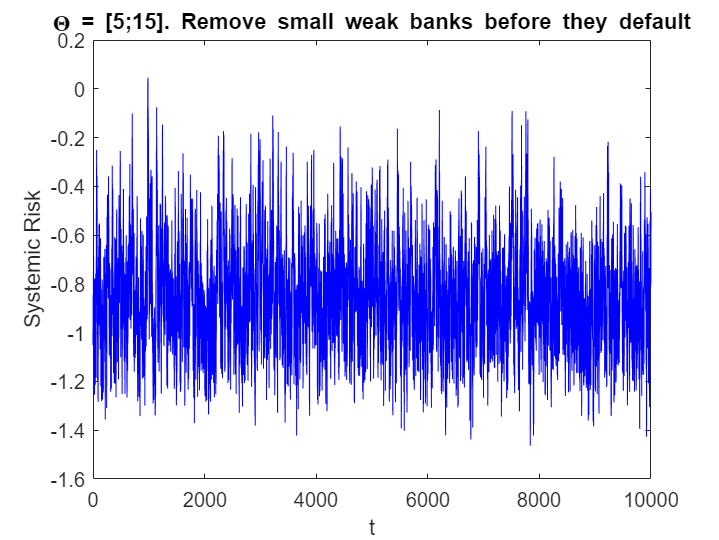

theta = 6;
A = BigSmallGraph(N, 5/6, 2.5, 0.5);
x = SolveSDE(t, N, h, sig, theta, @(t, x) WeakLinkHetero(x, A, 0, 0));
PlotSDE(t, x);
title("\Theta = [5;15]. Remove small weak banks before they default")

Remove weak and small banks

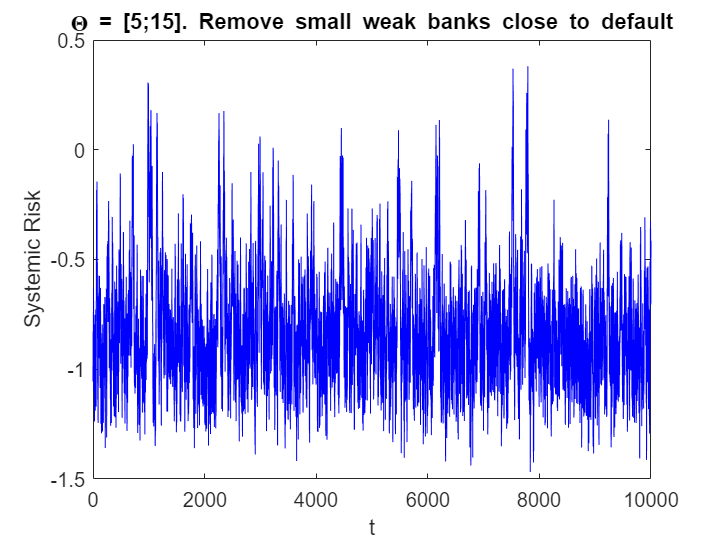

theta = 6;
A = BigSmallGraph(N, 5/6, 2.5, 0.5);
x = SolveSDE(t, N, h, sig, theta, @(t, x) WeakLinkHetero(x, A, 0.5, 0));
PlotSDE(t, x);
title("\Theta = [5;15]. Remove small weak banks close to default")

Benchmark (don't remove any banks)

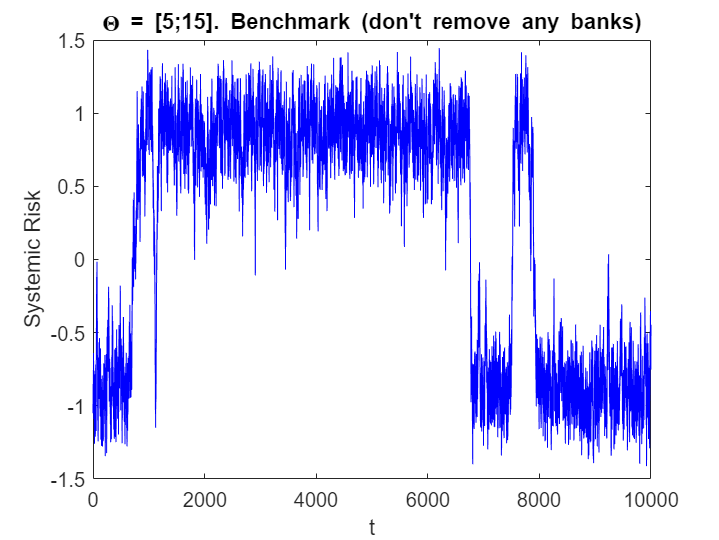

theta = 6;
A = BigSmallGraph(N, 5/6, 2.5, 0.5);
x = SolveSDE(t, N, h, sig, theta, @(t, x) WeakLinkHetero(x, A, 3, 0));
PlotSDE(t, x);
title("\Theta = [5;15]. Benchmark (don't remove any banks)")